clear all, clc;


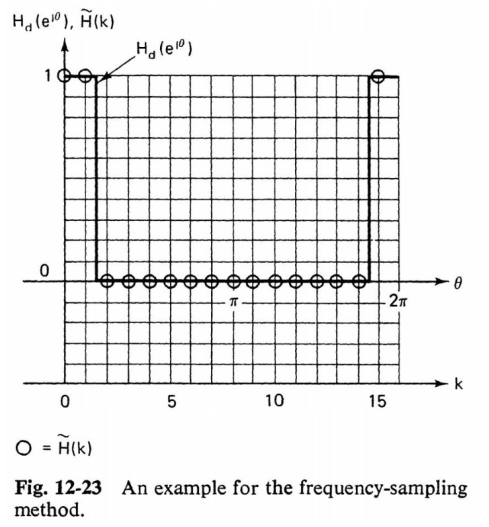

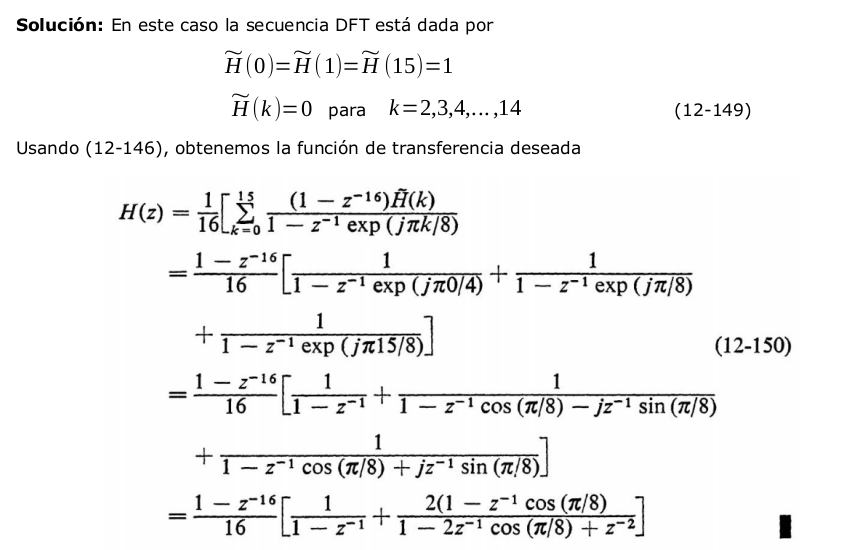

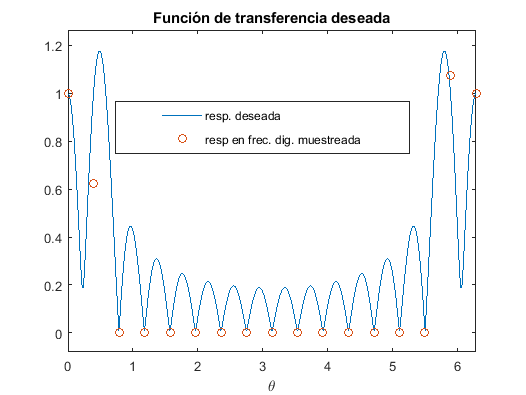


syms k 'integer';
syms z 'real';

H(z)=(1-z^-16)/16*(1/(1-z^-1)+ 2*(1-z^-1*cos(pi/8))/(1- 2*z^-1 * cos(pi/8)+z^-2) );

syms theta 'real';

clf; ezplot( abs( H(exp(j*theta) ) ) ,[ 0, 2*pi]),

hold on;
plot([0:pi/8:2*pi], abs([limit( H(exp(j*theta )), theta , 0) H(exp(j*[pi/8:pi/8:2*pi]) ) ]),'o');

legend('resp. deseada', 'resp en frec. dig. muestreada');
title('Función de transferencia deseada')
legend('Position',[0.23544,0.61655,0.52658,0.12331]);
hold off;